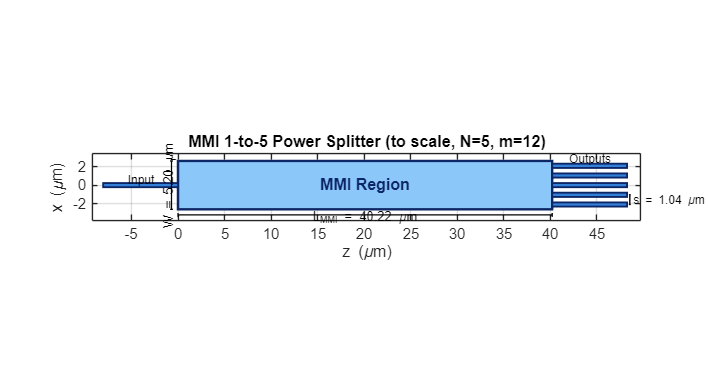

clear; clc; close all;

% Given parameters
lambda = 1.55e-6;   % um
a = 0.225e-6;       % um
n1 = 2.31;   
n0 = 1.46;
N = 5;              % MMI 1-to-N power splitter

m = 2*(N+1);
v = m*pi/2;
w = v*lambda/(pi*sqrt(n1^2-n0^2));

L_MMI = n1*w^2/lambda;
L = L_MMI / 5;
s = w / 5;

% Convert to um
w_um     = w     * 1e6;
L_MMI_um = L_MMI * 1e6;
L_um     = L     * 1e6;
s_um     = s     * 1e6;
wg_w     = 2*a   * 1e6;   % waveguide width in um
y_out = (-(N-1)/2 : 1 : (N-1)/2) * s_um;

figure('Color','w','Position',[100 100 950 520]);
hold on; axis equal;

mmi_color = [0.55 0.78 0.98];
wg_color  = [0.20 0.50 0.85];
ec        = [0.05 0.15 0.40];

% MMI region
rectangle('Position',[0, -w_um/2, L_MMI_um, w_um], ...
    'FaceColor', mmi_color, 'EdgeColor', ec, 'LineWidth', 1.8);

% Input waveguide
rectangle('Position',[-L_um, -wg_w/2, L_um, wg_w], ...
    'FaceColor', wg_color, 'EdgeColor', ec, 'LineWidth', 1.4);

% Output waveguides
for i = 1:N
    rectangle('Position',[L_MMI_um, y_out(i)-wg_w/2, L_um, wg_w], ...
        'FaceColor', wg_color, 'EdgeColor', ec, 'LineWidth', 1.4);
end

% --- Dimension: MMI length (horizontal) ---
ya = -w_um/2 - 0.6;
line([0 L_MMI_um],[ya ya],'Color','k','LineWidth',1.0);
line([0 0],[ya-0.2 ya+0.2],'Color','k','LineWidth',1.0);
line([L_MMI_um L_MMI_um],[ya-0.2 ya+0.2],'Color','k','LineWidth',1.0);
text(L_MMI_um/2, ya-0.35, sprintf('L_{MMI} = %.2f \\mum', L_MMI_um), ...
    'HorizontalAlignment','center','FontSize',10);

% --- Dimension: MMI width (vertical) ---
xa = -0.7;
line([xa xa],[-w_um/2 w_um/2],'Color','k','LineWidth',1.0);
line([xa-0.15 xa+0.15],[-w_um/2 -w_um/2],'Color','k','LineWidth',1.0);
line([xa-0.15 xa+0.15],[ w_um/2  w_um/2],'Color','k','LineWidth',1.0);
text(xa-0.15, 0, sprintf('W = %.2f \\mum', w_um), ...
    'HorizontalAlignment','center','FontSize',10,'Rotation',90);

% --- Dimension: output spacing ---
if N > 1
    xs = L_MMI_um + L_um + 0.3;
    line([xs xs],[y_out(1) y_out(2)],'Color','k','LineWidth',1.0);
    line([xs-0.1 xs+0.1],[y_out(1) y_out(1)],'Color','k','LineWidth',1.0);
    line([xs-0.1 xs+0.1],[y_out(2) y_out(2)],'Color','k','LineWidth',1.0);
    text(xs+0.2, (y_out(1)+y_out(2))/2, sprintf('s = %.2f \\mum', s_um), ...
        'FontSize',9,'VerticalAlignment','middle');
end

% --- Labels ---
text(L_MMI_um/2, 0, 'MMI Region', ...
    'HorizontalAlignment','center','FontSize',12,'FontWeight','bold','Color',ec);
text(-L_um/2, wg_w + 0.15, 'Input', ...
    'HorizontalAlignment','center','FontSize',9,'Color','k');
text(L_MMI_um + L_um/2, w_um/2 + 0.25, 'Outputs', ...
    'HorizontalAlignment','center','FontSize',9,'Color','k');

% --- Axes ---
xlabel('z (\mum)','FontSize',12);
ylabel('x (\mum)','FontSize',12);
title(sprintf('MMI 1-to-%d Power Splitter (to scale, N=%d, m=%d)', N, N, m), ...
    'FontSize',13,'FontWeight','bold');
xlim([-L_um-1.2,  L_MMI_um+L_um+1.5]);
ylim([-w_um/2-1.2, w_um/2+0.8]);
set(gca,'FontSize',11,'Box','on');
grid on;
hold off;